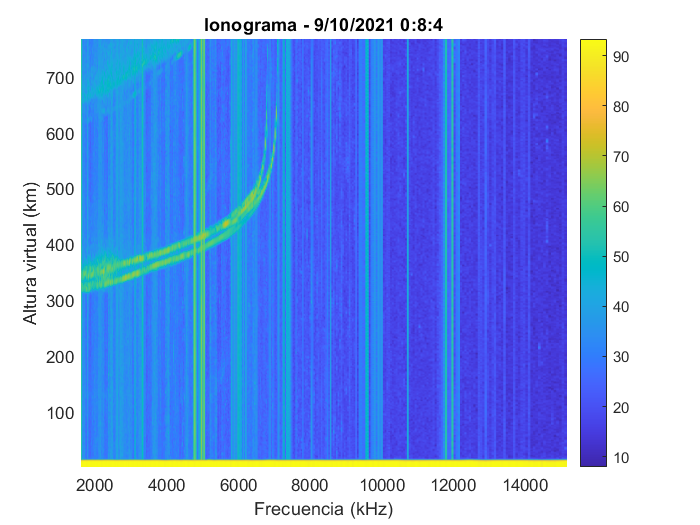

%% Plotear y guardar imagenes - O Mode Power
clc; clear; clf, close all;

%folderI = '/MATLAB Drive/TesisIonogramas/CodeData/Imagenes_ionogramas/Dificil';
MainFolder = 'D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Imagenes_ionogramas\Dificil\';
folderI = [MainFolder, 'NGI'];

fileList = dir(fullfile(folderI, '/*.ngi'));
randomIdx = randi(length(fileList), 1, 1);

cd(folderI);
%zippedDataFrame = 'JM91J_2020276010804.ngi';
zippedDataFrame = fileList(randomIdx).name;

% Date
Seconds = num2str(ncread(zippedDataFrame,'second'));
Minutes = num2str(ncread(zippedDataFrame,'minute'));
Hour    = num2str(ncread(zippedDataFrame,'hour'  ));
Day     = num2str(ncread(zippedDataFrame,'day'   ));
Month   = num2str(ncread(zippedDataFrame,'month' ));
Year    = num2str(ncread(zippedDataFrame,'year'  ));

% Data
FreqData            = double(ncread(zippedDataFrame,'Frequency'  )); % kHz
RangeData           = double(ncread(zippedDataFrame,'Range'      )); % km
totalpowerData      = double(ncread(zippedDataFrame,'total_power')); % Db
NoisetotalpowerData = double(ncread(zippedDataFrame,'total_noise'))';% Db

% Plot totalpowerData
figure(1);
h = pcolor(FreqData, RangeData, totalpowerData);
set(h, 'edgecolor','none'); colorbar; %colormap('gray');%caxis([0 1]);
set(gca,'YDir','normal');

title(['Ionograma - ', Month, '/', Day, '/', Year, ' ', ... 
    Hour, ':', Minutes, ':', Seconds]);
ylabel('Altura virtual (km)'); xlabel('Frecuencia (kHz)');


titlelabel = strrep(zippedDataFrame,'.ngi','');
%saveas(gcf,[titlelabel,'_totalpower.png'])

% cd(myFolder);
ncolumnsXnrows = size(totalpowerData);

%% Saving Images
%cd('D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Imagenes_ionogramas\Dificil\IonogramImage');
path4Sav = [MainFolder, 'IonogramImages\'];

for k=1:length(fileList)
    zippedDataFrame = fileList(k).name;
    totalpowerData = uint8(flip(ncread(zippedDataFrame,'total_power'))); % Db
    
    imwrite(totalpowerData, [path4Sav, zippedDataFrame,'_totalpower.tif']);
end


%% tracking?
clf
for k=1:length(fileList)
    clear zippedDataFrame totalpowerData
    zippedDataFrame = fileList(k).name;
    totalpowerData = double(ncread(zippedDataFrame,'total_power')); % Db
    
    % Plot totalpowerData
    imagesc(flip(totalpowerData)), hold on;
    pause(1);
end

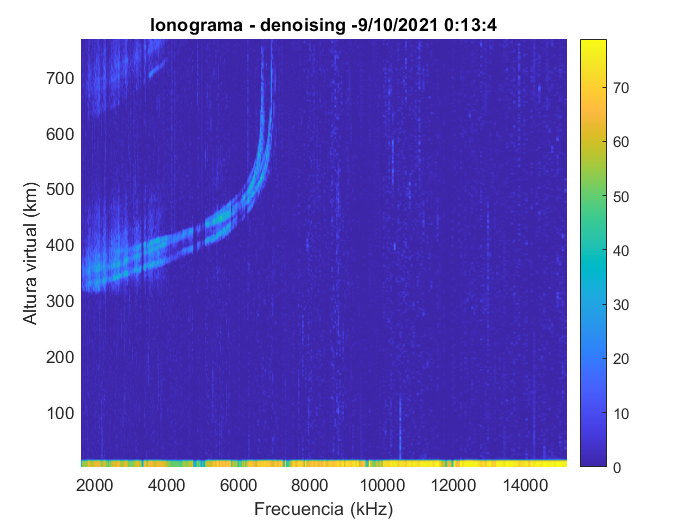

%% Denoising - Noise lvl array

iIonDenoising = zeros( ncolumnsXnrows(1), ncolumnsXnrows(2));
for i = 1:ncolumnsXnrows(2)
    for ii = 1:ncolumnsXnrows(1)
        iIonDenoising(ii, i) = totalpowerData(ii, i) - NoisetotalpowerData(i);
        if iIonDenoising(ii, i) < 0 
            iIonDenoising(ii, i) = 0; 
        end
    end
end

% Plot Ionogram - Noise lvl array
figure(2);
h = pcolor(FreqData, RangeData, iIonDenoising);
set(h, 'edgecolor','none'); colorbar; %colormap('gray');%caxis([0 1]);
set(gca,'YDir','normal');
title(['Ionograma - denoising -', Month, '/', Day, '/', Year, ' ', ... 
    Hour, ':', Minutes, ':', Seconds]);
ylabel('Altura virtual (km)'); xlabel('Frecuencia (kHz)');


%saveas(gcf,[titlelabel,'_totalpower_den_NoiseLvlArray.png'])

%% Saving Images - Denoising
%cd('D:\Matlab\MatlabDrive\TesisIonogramas\CodeData\Imagenes_ionogramas\Dificil\IonogramImage');
path4Sav = [MainFolder, 'IonogramImages\'];
iIonDenoising = zeros( ncolumnsXnrows(1), ncolumnsXnrows(2));

for k=1:length(fileList)
    zippedDataFrame = fileList(k).name;
    totalpowerData = double(ncread(zippedDataFrame,'total_power')); % Db
    
    for i = 1:ncolumnsXnrows(2)
        for ii = 1:ncolumnsXnrows(1)
            iIonDenoising(ii, i) = totalpowerData(ii, i) - NoisetotalpowerData(i);
            if iIonDenoising(ii, i) < 0 
                iIonDenoising(ii, i) = 0; 
            end
        end
    end
    %totalpowerData = uint8(flip(ncread(zippedDataFrame,'total_power'))); % Db
    
    imwrite(uint8(flip(iIonDenoising)), [path4Sav, zippedDataFrame,'_totalpower.tif']);
end

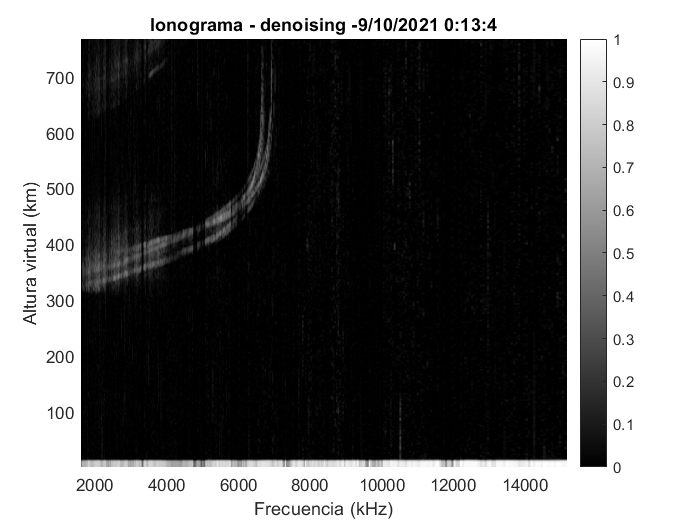

%% Binarization & Grayscale

iIonDenBin = mat2gray(iIonDenoising); % binarization
iIonDenoisingVar = iIonDenoising;
% test = medfilt2(test);        % 2-D median filtering

% Plot Ionogram - Bin & Grayscale
figure(3);
h = pcolor(FreqData, RangeData, iIonDenBin);
set(h, 'edgecolor','none'); colorbar; colormap('gray'); caxis([0 1]);
set(gca,'YDir','normal');
title(['Ionograma - denoising -', Month, '/', Day, '/', Year, ' ', ... 
    Hour, ':', Minutes, ':', Seconds]);
ylabel('Altura virtual (km)'); xlabel('Frecuencia (kHz)');

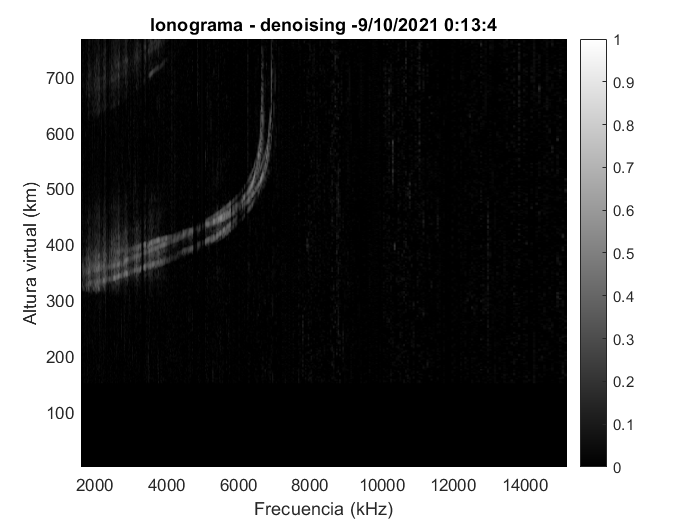


%saveas(gcf,[titlelabel,'_totalpower_den_bin_grayScale.png'])

%% Denoising - Getting rid of the traces under 150 km

heightScaled = linspace(round(min(RangeData)), round(max(RangeData)), ncolumnsXnrows(1));
iIonDenGROfTraces = iIonDenBin;

for i = 1:length(heightScaled)
    if (heightScaled(i) <= 150)
        iIonDenGROfTraces(i, :) = 0;
        iIonDenoisingVar(i, :) = 0;
    end
end

% Plot Ionogram - Under 150 km
figure(4);
h = pcolor(FreqData, RangeData, iIonDenGROfTraces);
set(h, 'edgecolor','none'); colorbar; colormap('gray'); caxis([0 1]);
set(gca,'YDir','normal');
title(['Ionograma - denoising -', Month, '/', Day, '/', Year, ' ', ... 
    Hour, ':', Minutes, ':', Seconds]);
ylabel('Altura virtual (km)'); xlabel('Frecuencia (kHz)');


%saveas(gcf,[titlelabel,'_totalpower_den_Under150.png'])

    sobelzzz = edge(iIonDenBin, 'Canny');
    imshow(sobelzzz)    

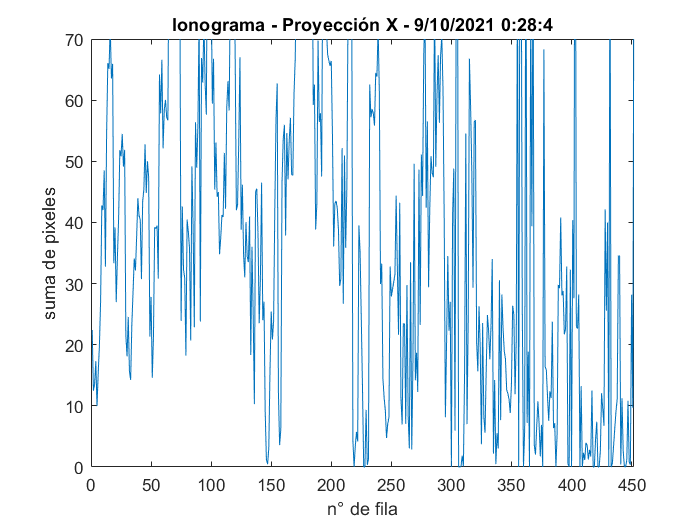

%% Projection

iIonDenProj = iIonDenGROfTraces;

proyx=zeros(ncolumnsXnrows(2), 1); % Para x
proyx_nFila = linspace(1,ncolumnsXnrows(2),ncolumnsXnrows(2));

proyy=zeros(ncolumnsXnrows(1), 1); % Para Y
proyy_nFila = linspace(1,ncolumnsXnrows(1),ncolumnsXnrows(1));

% Get the projection of the X axis
for i = 1:ncolumnsXnrows(2)
    for j = 1:ncolumnsXnrows(1)
        proyx(i) = proyx(i) + iIonDenProj(j,i);
    end
end

% Get the projection of the Y axis
for i = 1:ncolumnsXnrows(1)
    for j = 1:ncolumnsXnrows(2)
        proyy(i) = proyy(i) + iIonDenProj(i,j);
    end
end

% figure(5)
% h = pcolor(FreqData, RangeData, iIonDenProj);
% set(h, 'edgecolor','none'); colorbar; colormap('gray'); caxis([0 1]);
% set(gca,'YDir','normal');
% title(['Ionograma - ', Month, '/', Day, '/', Year, ' ', ... 
%     Hour, ':', Minutes, ':', Seconds]);
% ylabel('Altura virtual (km)'); xlabel('Frecuencia (kHz)');

figure,
plot(proyx_nFila, proyx);
set(gca,'YDir','normal');
title(['Ionograma - Proyección X - ', Month, '/', Day, '/', Year, ' ', ... 
    Hour, ':', Minutes, ':', Seconds]);
ylabel('suma de pixeles'); xlabel('n° de fila');

xlim([0 length(proyx)])
ylim([0.0 70])

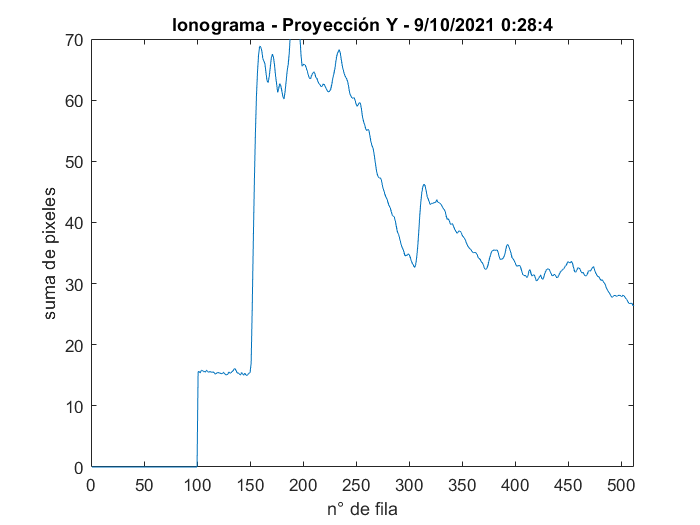

%saveas(gcf,'ProyeccionX.png')

figure,
plot(proyy_nFila, proyy);
set(gca,'YDir','normal');
title(['Ionograma - Proyección Y - ', Month, '/', Day, '/', Year, ' ', ... 
    Hour, ':', Minutes, ':', Seconds]);
ylabel('suma de pixeles'); xlabel('n° de fila');

xlim([0 length(proyy)])
ylim([0.0 70])

%% Projection filtering
% a(n) para X Este usan en el paper!!!!!

% Smooth projection 
gwin = gausswin(17);

gwin = gwin/sum(gwin);
proyxFiltGauss = conv(proyx, gwin, 'same');

plot(proyx); hold on
plot(proyxFiltGauss);

set(gca,'YDir','normal');
title(['Ionograma - Proyección X - Gauss - ', Month, '/', Day, '/', Year, ' ', ... 
    Hour, ':', Minutes, ':', Seconds]);
ylabel('suma de pixeles'); xlabel('n° de fila'); legend('Señal original','Señal filtrada')
%saveas(gcf,[titlelabel,'_proyeccionX_Gauss.png'])

Ax = mean(proyxFiltGauss); % Mean of proyx
k = 1; % Empirical value % not needed for a higher value of gwin
thresholdx = k*Ax;

iIonDenProjFilt = iIonDenProj;
% iIonDenProjFilt = imgaussfilt(iIonDenProjFilt);

for x = 1:ncolumnsXnrows(2)
    for y = 1:ncolumnsXnrows(1)
        if proyxFiltGauss(x) < thresholdx
            iIonDenProjFilt(y,x) = 0;
        end
    end
end

% X projection after filt.
proyxFilt = zeros(ncolumnsXnrows(2),1); % Para x

for x = 1:ncolumnsXnrows(2)
    for y = 1: ncolumnsXnrows(1)
        proyxFilt(x) = proyxFilt(x)+iIonDenProjFilt(y,x);
    end
end

figure(7);
plot(proyx); hold on
plot(proyxFilt)
set(gca,'YDir','normal');
title(['Ionograma - Proyección X - Filtered - ', Month, '/', Day, '/', Year, ' ', ... 
    Hour, ':', Minutes, ':', Seconds]);
ylabel('suma de pixeles'); xlabel('n° de fila'); legend('Señal original','Señal filtrada')
%saveas(gcf,[titlelabel,'_proyeccionX_Filtered.png'])

figure(8);
% subplot(1,2,1)
h = pcolor(FreqData, RangeData, mat2gray(totalpowerData));
set(h, 'edgecolor','none'); colorbar; caxis([0 1]);
set(gca,'YDir','normal');
title(['Ionograma - Original']);
ylabel('Altura virtual (km)'); xlabel('Frecuencia (kHz)');
%saveas(gcf,[titlelabel,'_totalpower_original.png'])

figure;
% subplot(1,2,2)
h = pcolor(FreqData, RangeData, iIonDenProjFilt);
set(h, 'edgecolor','none'); colorbar; colormap('gray'); caxis([0 1]);
set(gca,'YDir','normal');
title(['Ionograma - Pre procesado']);
xlabel('Frecuencia (kHz)');
%saveas(gcf,[titlelabel,'_totalpower_PreProc.png'])


%% Dilation
SE = strel('rectangle',[3 3]); % lo cambie de 3x3 a 4x6 para que se parezca al paper
iIonDil = imdilate(iIonDenProjFilt,SE);

figure(9);
h = pcolor(FreqData, RangeData, iIonDil);
set(h, 'edgecolor','none'); colorbar; %colormap('gray'); caxis([0 1]);
set(gca,'YDir','normal');
title(['Ionograma - Dilated - ', Month, '/', Day, '/', Year, ' ', ... 
    Hour, ':', Minutes, ':', Seconds]);
ylabel('Altura virtual (km)'); xlabel('Frecuencia (kHz)');


%% connected component labeling

iIonCCL = bwlabel(iIonDil); % Connected Componet Labeling
iIonCCLFiltered = iIonCCL;

rCenter = 0;
% cCenter=0;
 
for ii = min(min(iIonCCL)) : length(iIonCCL) : max(max(iIonCCL))
    [r, c] = find(iIonCCL == ii);
    rCenter = round((min(r) + max(r))/2);
    % cCenter = round((min(c) + max(c))/2);
    if (rCenter > round(heightScaled(100))) && (rCenter < round(heightScaled(550)))
    else
        iIonCCLFiltered(r,c) = 0; % Delete isolated
    end
end

% rCenterScaled = linspace(ncolumnsXnrows(1),1,1000);

figure(11); 
subplot(1,2,1); 
h = pcolor(FreqData, RangeData, iIonCCL);
set(h, 'edgecolor','none'); %colormap('gray');
set(gca,'YDir','normal');
title(['Ionograma - CCL - ', Month, '/', Day, '/', Year, ' ', ... 
    Hour, ':', Minutes, ':', Seconds]);
ylabel('Altura virtual (km)'); xlabel('Frecuencia (kHz)');

subplot(1,2,2);
h = pcolor(FreqData, RangeData, iIonCCLFiltered);
set(h, 'edgecolor','none'); colormap('gray');
set(gca,'YDir','normal');
title(['Ionograma - CCL Filtered - ', Month, '/', Day, '/', Year, ' ', ... 
    Hour, ':', Minutes, ':', Seconds]);
ylabel('Altura virtual (km)'); xlabel('Frecuencia (kHz)');

%%

iIonCCL = bwlabel(iIonDil); % Connected Componet Labeling

iIonCCLFiltered = iIonCCL;

% ----

[r, c] = find(iIonCCL==2);

IonCenter = iIonCCL(((min(r)):max(r)) , (min(c):max(c)));
figure; imagesc(IonCenter)

% floor((size(IonogramCCLFiltered(r,c))+1)/2) % center

iIonCCLFiltered(r,c)=0; % Delete isolated

figure(12); 
subplot(1,2,1); imagesc(iIonCCL); title('Ionograma - CCL')
subplot(1,2,2); imagesc(iIonCCLFiltered); title('Ionograma - CCL Filtered Manual')


%% Overlap
iIonCCLFiltered=mat2gray(iIonCCLFiltered);
IonDone = iIonDenProjFilt - iIonCCLFiltered;

for x = 1:ncolumnsXnrows(2)
    for y = 1: ncolumnsXnrows(1)
        if IonDone(y,x) <0.50
            IonDone(y,x)=0;
        end
    end
end

% zzz = imoverlay(IonogramCCLFiltered,totalpowerDtFiltered1);

figure(13); 
subplot(1,2,1); imagesc(totalpowerDt); title('Ionograma'); colormap('gray');
subplot(1,2,2); imagesc(IonDone); title('Ionograma - Final'); colormap('gray');
%% 

% plot(proyx); axis('off');
% saveas(gcf,'1.png')
imshow(imread('2.png'))

zzz1 = rgb2gray(imread('1.png'));
zzz2 = rgb2gray(imread('2.png'));

% Get size of existing image A.
[rowsA, colsA, numberOfColorChannelsA] = size(zzz2);
% Get size of existing image B.
[rowsB, colsB, numberOfColorChannelsB] = size(zzz1);
% See if lateral sizes match.
if rowsB ~= rowsA || colsA ~= colsB
    % Size of B does not match A, so resize B to match A's size.
    zzz1 = imresize(zzz1, [rowsA colsA]);
end


% imshow(zzz2)
err = immse(zzz2, zzz1);
figure; imshow(zzz2)
figure; imshow(zzz1)


%%
plot(zzz1(:,1))
